# Plot Gas Prices

This interaction is not graded. You can move to the next section when you are ready.

countries = string(table2array(readtable("../data/gPrices.xlsx", "Sheet", "countries", "ReadVariableNames", false)));
prices = table2array(readtable("../data/gPrices.xlsx", "Sheet", "prices", "ReadVariableNames", false));
Year = table2array(readtable("../data/gPrices.xlsx", "Sheet", "Year", "ReadVariableNames", false));
whos

  Name             Size            Bytes  Class      Attributes

  Year            19x1               152  double               
  countries        1x10              668  string               
  ctry             1x1               166  string               
  ctryPrices      19x1               152  double               
  idx              1x1                 8  double               
  idxVec           1x10               10  logical              
  prices          19x10             1520  double               



## User Input

Select country.

ctry = countries(1);
idxVec = strcmp(ctry, countries);
idx = find(idxVec)

idx = 1

## Price Analysis

Extract data for the chosen country

ctryPrices = prices(:, idx);

Make plot

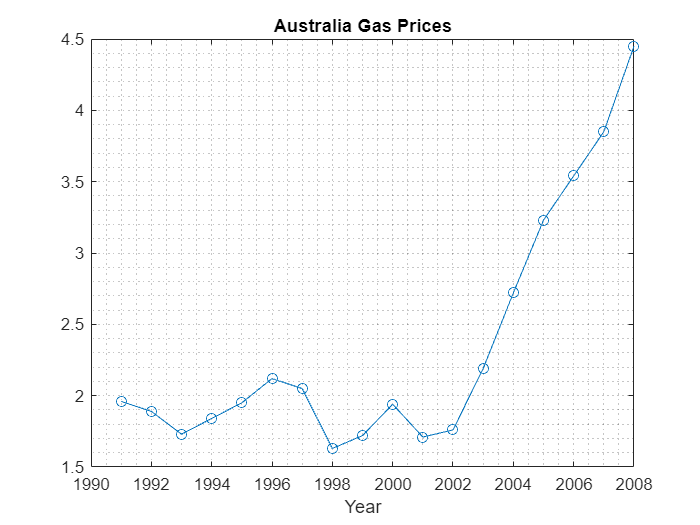

plot(Year, ctryPrices, "o-")
grid minor
xlabel("Year")
title(ctry + " Gas Prices")